## Getting videos

### Create paths:

videoList = "toCrop_list.txt"

videoList = "toCrop_list.txt"


% CREATING PATHS
% video folder
videoFolderPath = strcat('C:\Users\M.Vulf\Desktop\_Generating droplets\VIDEO_DATA');
% cropping folder
croppingFolderPath = strcat(videoFolderPath, '\', "cropping_data");
% data of cropping
dataPath = strcat(croppingFolderPath, '\', "cropping_video.csv");
 
dataCell = splitlines(fileread(strcat(croppingFolderPath,'\',videoList)));
disp(strcat("Count of videos: ", string(length(dataCell))));

Count of videos: 50


### Load videos from list:

Choose analyzing range and click "Load videos"

loadRange =[1 inf];

% checking the end of the analyzingRange
if length(dataCell) < loadRange(2)
    loadRange(2) = length(dataCell);
end
 

uploadCount = loadRange(2) + 1 - loadRange(1);
disp(strcat("Total count of upload videos: ", string(uploadCount)));

Total count of upload videos: 50



allVideoNames = cell(1,loadRange(2));
allObj = cell(1,loadRange(2));
allVideos = cell(1,loadRange(2));

parfor cellNum = loadRange(1):loadRange(2)
    allVideoNames{cellNum} = string(dataCell{cellNum});
    disp(strcat(string(cellNum),") ", allVideoNames{cellNum}));
    allObj{cellNum} = VideoReader(strcat(videoFolderPath,...
        '\', allVideoNames{cellNum}));
    % total frame range
    frameRange = [1 allObj{cellNum}.NumFrames];
    disp(strcat("Loading ", string(frameRange(2)), " frames..."));
    
    allVideos{cellNum} = allObj{cellNum}.read(frameRange);
    disp("...video uploaded.");
    
end

50) 0485_photron_avi.avi
Loading 901 frames...
...video uploaded.
49) 0484_photron_avi.avi
Loading 901 frames...
...video uploaded.
48) 0483_photron_avi.avi
Loading 901 frames...
...video uploaded.
47) 0482_photron_avi.avi
Loading 901 frames...
...video uploaded.
46) 0481_photron_avi.avi
Loading 901 frames...
...video uploaded.
45) 0480_photron_avi.avi
Loading 901 frames...
...video uploaded.
44) 0479_photron_avi.avi
Loading 901 frames...
...video uploaded.
43) 0478_photron_avi.avi
Loading 901 frames...
...video uploaded.
42) 0477_photron_avi.avi
Loading 901 frames...
...video uploaded.
41) 0476_photron_avi.avi
Loading 901 frames...
...video uploaded.
40) 0475_photron_avi.avi
Loading 901 frames...
...video uploaded.
39) 0474_photron_avi.avi
Loading 901 frames...
...video uploaded.
38) 0473_photron_avi.avi
Loading 901 frames...
...video uploaded.
37) 0472_photron_avi.avi
Loading 901 frames...
...video uploaded.
36) 0471_photron_avi.avi
Loading 901 frames...
...video uploaded.
35) 0470_p

#### Analyzing settings

Chose **analyzingRange**, 

**intensity threshold** *(from 1 to 256; what intensity in diffImage is a threshold for droplet appearing)*, 

**scale koeficient** (*for increasing peaks high*),

**frame limit** *(count of frames, exceeding of which without EMD-changing means new droplets), *

**smoothSpan** - span of the moving average (1 ...).

**polyOrder** - order of polinominal fitting.

**baseSide** - side for finding count of crops.

analyzeFlag = false

analyzeFlag = logical
   0


analyzingList ="analyze_list.txt";

threshold =  70

threshold = 70

scaleKoef = [1 0.0]

scaleKoef =      1     0


frameLimit = 40

frameLimit = 40

smoothSpan = 5

smoothSpan = 5

% SET order of polinominal fit
upPolyOrder = -1

upPolyOrder = -1

downPolyOrder = -1

downPolyOrder = -1

polyOrder = [upPolyOrder downPolyOrder];
% SET Threshold quantile value of detrending signal [up down]
quantileThreshold  = [1.0 0.80]

quantileThreshold =     1.0000    0.8000


baseSide = "down"

baseSide = "down"

% SET BASE SIDE (1 - up; 2 - down)
switch baseSide
    case "up"
        baseFrameSide = 1;
    case "down"
        baseFrameSide = 2;
    otherwise 
        baseFrameSide = 2;
end

% changing EMD-levels
upScaleKoef = scaleKoef(1); 
downScaleKoef = scaleKoef(2);

% SET Quantile value (0...1)
maxEMDQuantileValue = [0.90 0.90];
maxSecDifQuantileValue = [0.5 0.5];

% SET Max distance (in UpDownKoef*frameLimit between peaks)
UpDownKoef = 3;

% create analyzing cells
if analyzeFlag
    analyzeCell = splitlines(fileread(strcat(croppingFolderPath,'\',analyzingList)));
else
    analyzeCell = cellfun(@char,allVideoNames,'UniformOutput',false)';
end

disp(strcat("Count of videos: ", string(length(analyzeCell))));

Count of videos: 50


#### VIDEO ANALYZING:

Before clicking "ANALYZE", click "APPLY SETTINGS"

1) ANALYZING: 0436_photron_avi.avi


Count of detected crops: 2


Figure & template were saved


Last row:


Saved row:


    {[436]}    {'245-323,481-552'}



2) ANALYZING: 0437_photron_avi.avi


Count of detected crops: 2


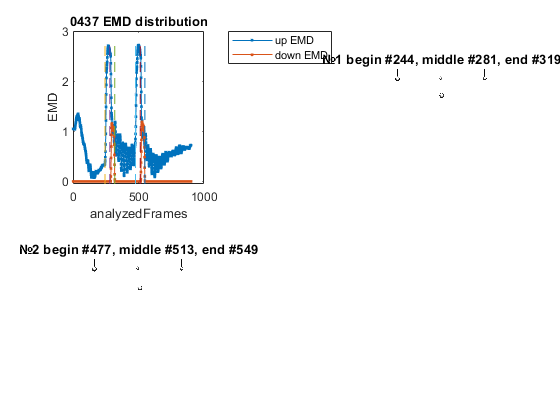

Figure & template were saved


Last row:


Saved row:


    {[437]}    {'244-319,477-549'}



3) ANALYZING: 0438_photron_avi.avi


Count of detected crops: 2


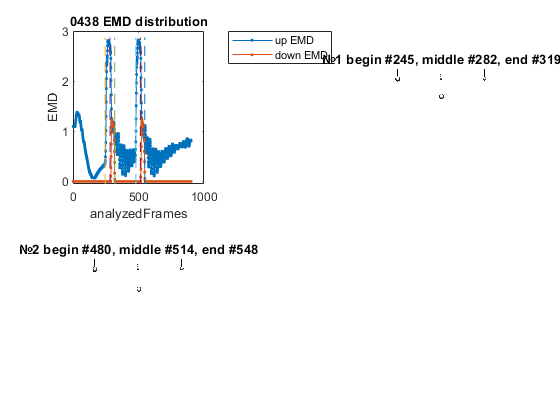

Figure & template were saved


Last row:


Saved row:


    {[438]}    {'245-319,480-548'}



4) ANALYZING: 0439_photron_avi.avi


Count of detected crops: 2


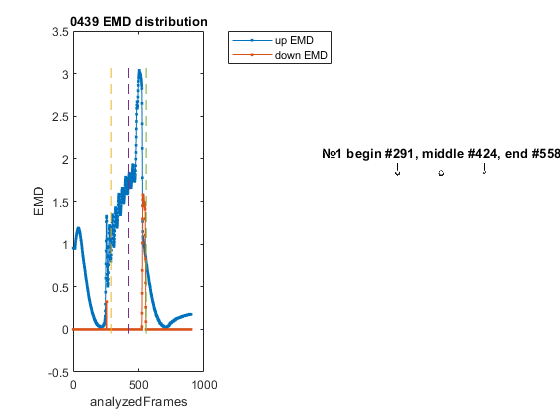

Figure & template were saved


Last row:


Saved row:


    {[439]}    {'291-558'}



5) ANALYZING: 0440_photron_avi.avi


Count of detected crops: 2


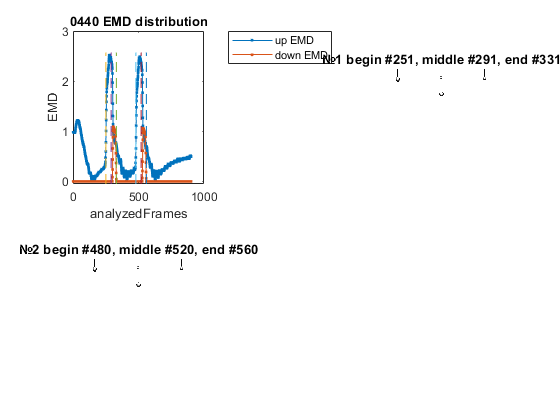

Figure & template were saved


Last row:


Saved row:


    {[440]}    {'251-331,480-560'}



6) ANALYZING: 0441_photron_avi.avi


Count of detected crops: 2


Figure & template were saved


Last row:


Saved row:


    {[441]}    {'250-325,479-555'}



7) ANALYZING: 0442_photron_avi.avi


Count of detected crops: 2


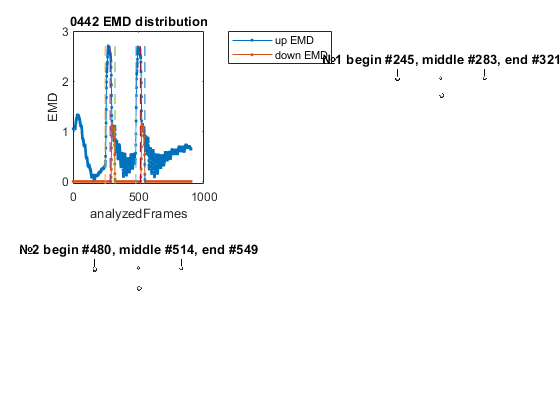

Figure & template were saved


Last row:


Saved row:


    {[442]}    {'245-321,480-549'}



8) ANALYZING: 0443_photron_avi.avi


Count of detected crops: 2


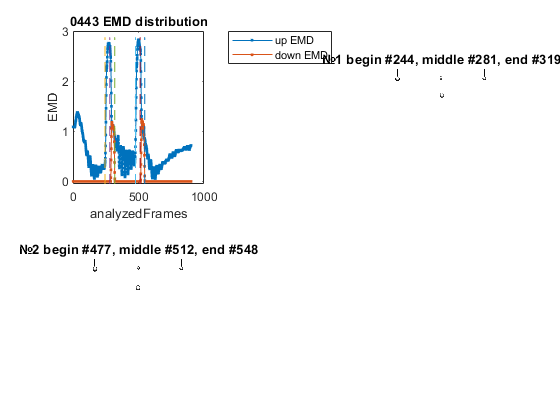

Figure & template were saved


Last row:


Saved row:


    {[443]}    {'244-319,477-548'}



9) ANALYZING: 0444_photron_avi.avi


Count of detected crops: 2


Figure & template were saved


Last row:


Saved row:


    {[444]}    {'245-318,480-547'}



10) ANALYZING: 0445_photron_avi.avi


Count of detected crops: 2


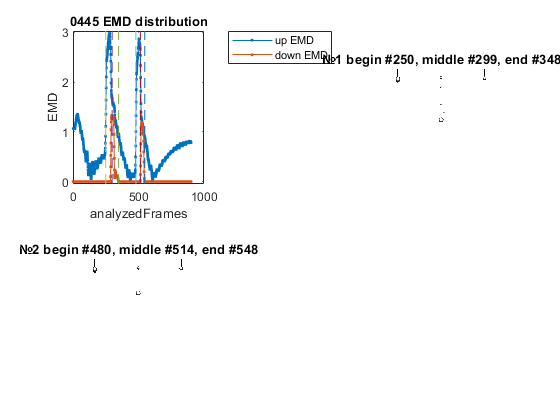

Figure & template were saved


Last row:


Saved row:


    {[445]}    {'250-348,480-548'}



11) ANALYZING: 0446_photron_avi.avi


Count of detected crops: 1


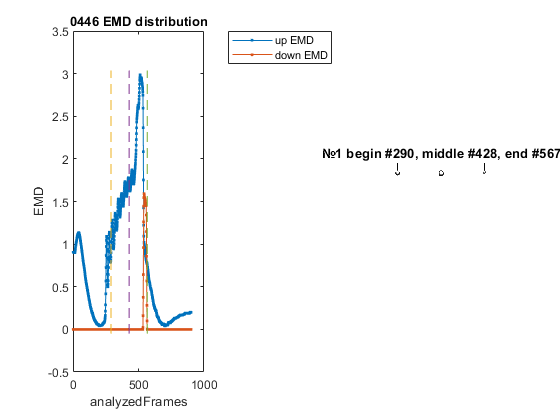

Figure & template were saved


Last row:


Saved row:


    {[446]}    {'290-567'}



12) ANALYZING: 0447_photron_avi.avi


Count of detected crops: 1


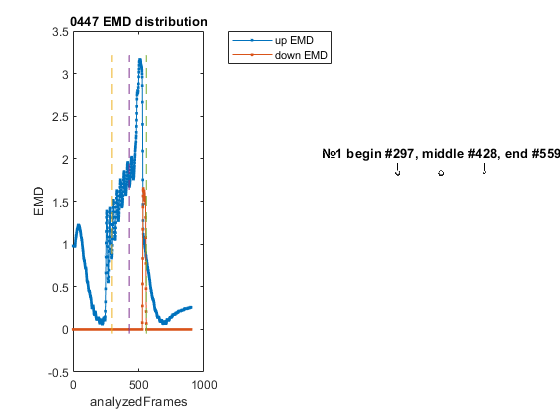

Figure & template were saved


Last row:


Saved row:


    {[447]}    {'297-559'}



13) ANALYZING: 0448_photron_avi.avi


Count of detected crops: 1


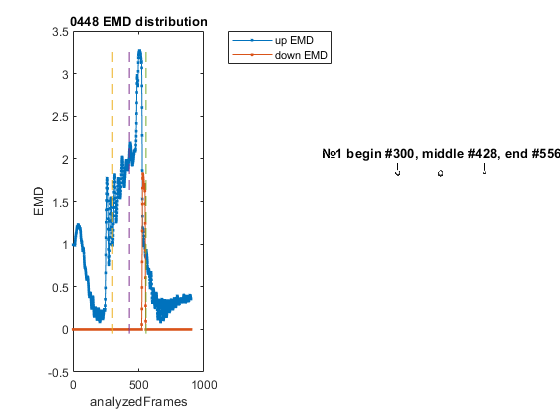

Figure & template were saved


Last row:


Saved row:


    {[448]}    {'300-556'}



14) ANALYZING: 0449_photron_avi.avi


Count of detected crops: 2


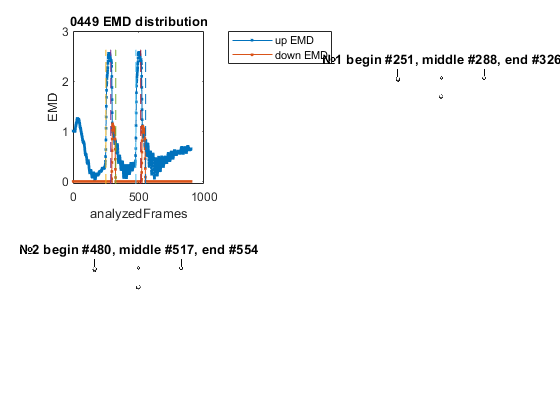

Figure & template were saved


Last row:


Saved row:


    {[449]}    {'251-326,480-554'}



15) ANALYZING: 0450_photron_avi.avi


Count of detected crops: 2


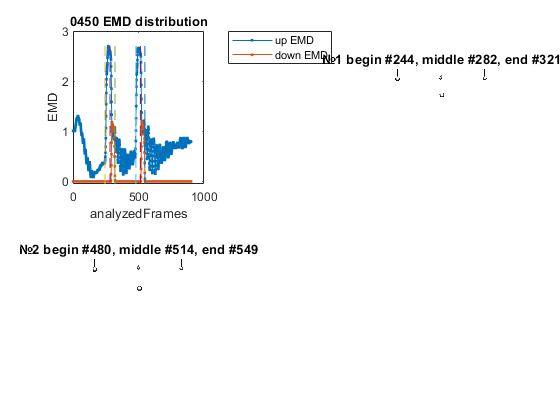

Figure & template were saved


Last row:


Saved row:


    {[450]}    {'244-321,480-549'}



16) ANALYZING: 0451_photron_avi.avi


Count of detected crops: 2


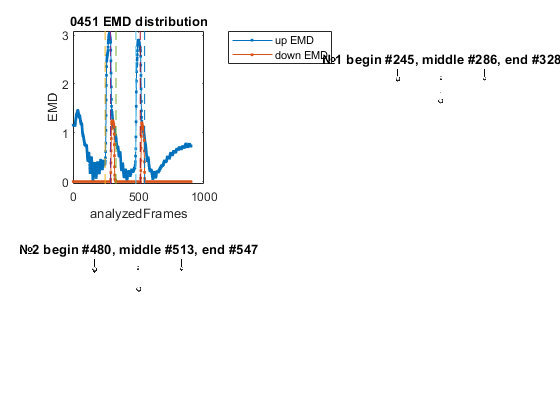

Figure & template were saved


Last row:


Saved row:


    {[451]}    {'245-328,480-547'}



17) ANALYZING: 0452_photron_avi.avi


Count of detected crops: 2


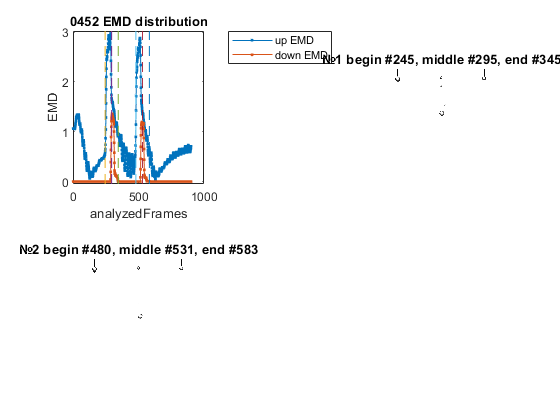

Figure & template were saved


Last row:


Saved row:


    {[452]}    {'245-345,480-583'}



18) ANALYZING: 0453_photron_avi.avi


Count of detected crops: 1


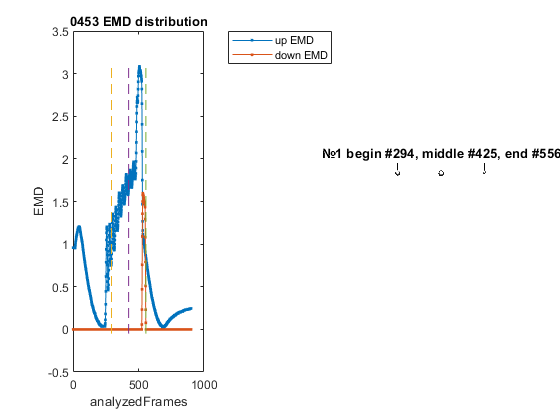

Figure & template were saved


Last row:


Saved row:


    {[453]}    {'294-556'}



19) ANALYZING: 0454_photron_avi.avi


Count of detected crops: 1


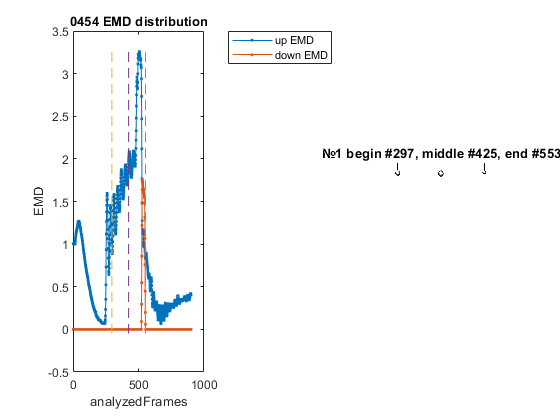

Figure & template were saved


Last row:


Saved row:


    {[454]}    {'297-553'}



20) ANALYZING: 0455_photron_avi.avi


Count of detected crops: 2


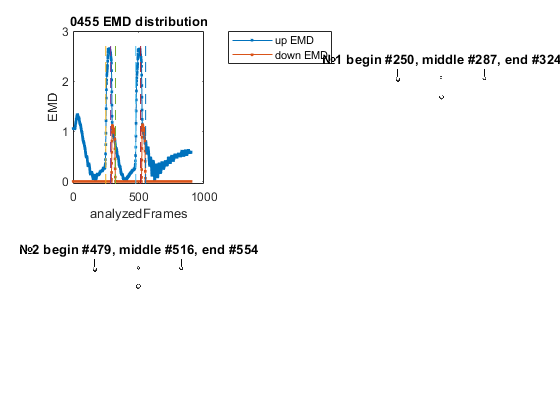

Figure & template were saved


Last row:


Saved row:


    {[455]}    {'250-324,479-554'}



21) ANALYZING: 0456_photron_avi.avi


Count of detected crops: 2


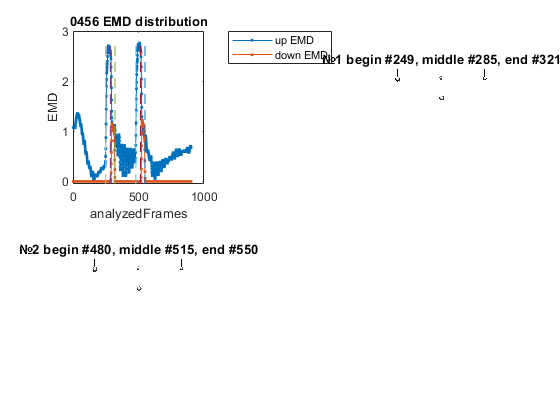

Figure & template were saved


Last row:


Saved row:


    {[456]}    {'249-321,480-550'}



22) ANALYZING: 0457_photron_avi.avi


Count of detected crops: 2


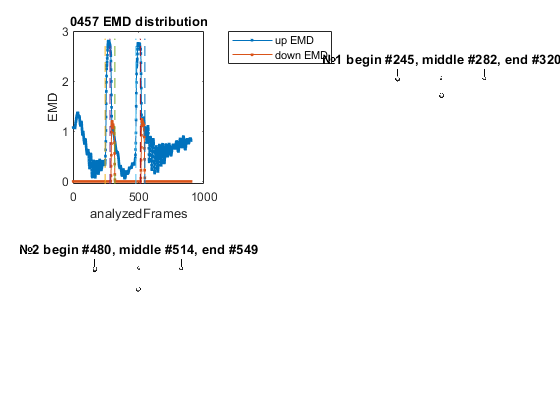

Figure & template were saved


Last row:


Saved row:


    {[457]}    {'245-320,480-549'}



23) ANALYZING: 0458_photron_avi.avi


Count of detected crops: 2


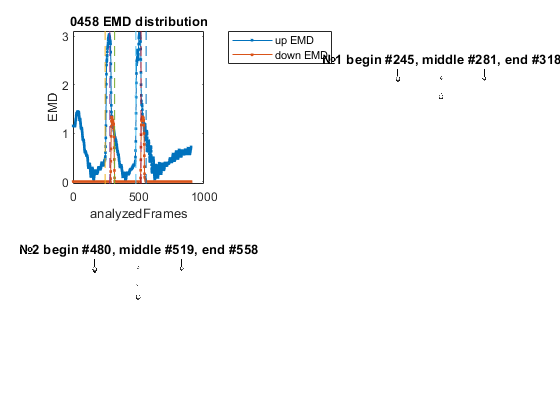

Figure & template were saved


Last row:


Saved row:


    {[458]}    {'245-318,480-558'}



24) ANALYZING: 0459_photron_avi.avi


Count of detected crops: 2


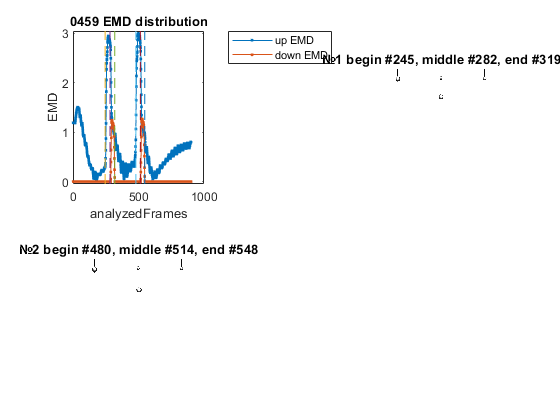

Figure & template were saved


Last row:


Saved row:


    {[459]}    {'245-319,480-548'}



25) ANALYZING: 0460_photron_avi.avi


Count of detected crops: 1


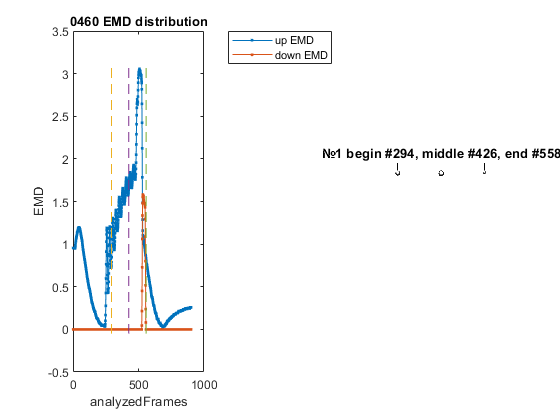

Figure & template were saved


Last row:


Saved row:


    {[460]}    {'294-558'}



26) ANALYZING: 0461_photron_avi.avi


Count of detected crops: 1


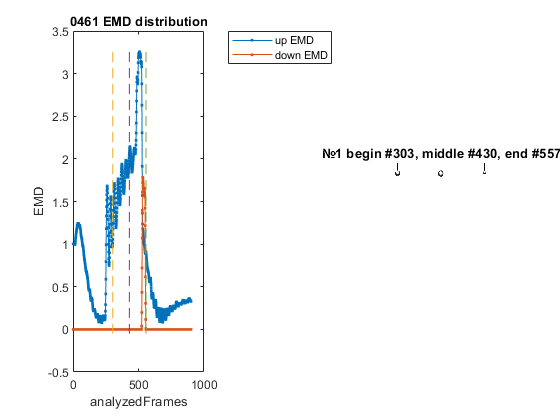

Figure & template were saved


Last row:


Saved row:


    {[461]}    {'303-557'}



27) ANALYZING: 0462_photron_avi.avi


Count of detected crops: 2


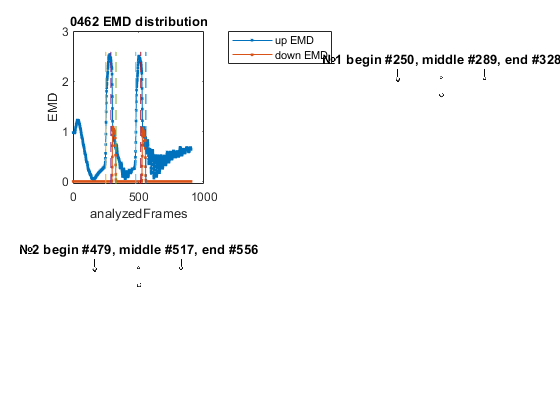

Figure & template were saved


Last row:


Saved row:


    {[462]}    {'250-328,479-556'}



28) ANALYZING: 0463_photron_avi.avi


Count of detected crops: 2


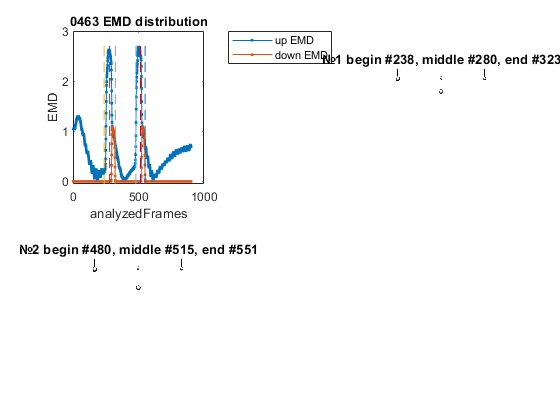

Figure & template were saved


Last row:


Saved row:


    {[463]}    {'238-323,480-551'}



29) ANALYZING: 0464_photron_avi.avi


Count of detected crops: 2


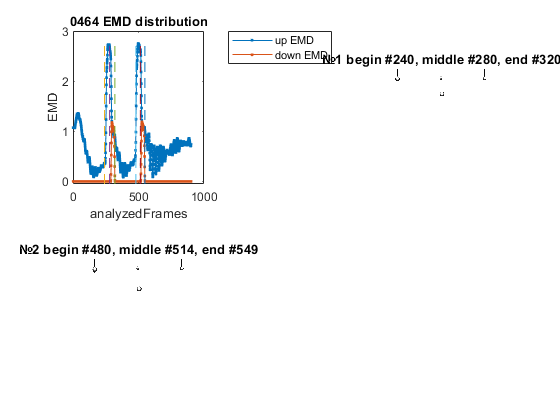

Figure & template were saved


Last row:


Saved row:


    {[464]}    {'240-320,480-549'}



30) ANALYZING: 0465_photron_avi.avi


Count of detected crops: 2


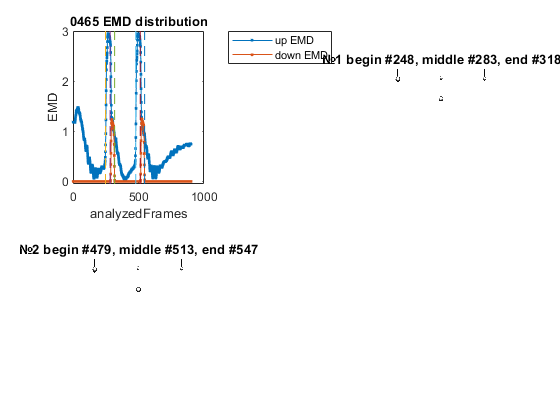

Figure & template were saved


Last row:


Saved row:


    {[465]}    {'248-318,479-547'}



31) ANALYZING: 0466_photron_avi.avi


Count of detected crops: 2


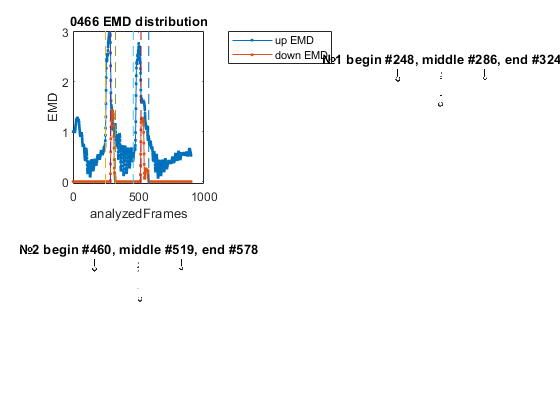

Figure & template were saved


Last row:


Saved row:


    {[466]}    {'248-324,460-578'}



32) ANALYZING: 0467_photron_avi.avi


Count of detected crops: 1


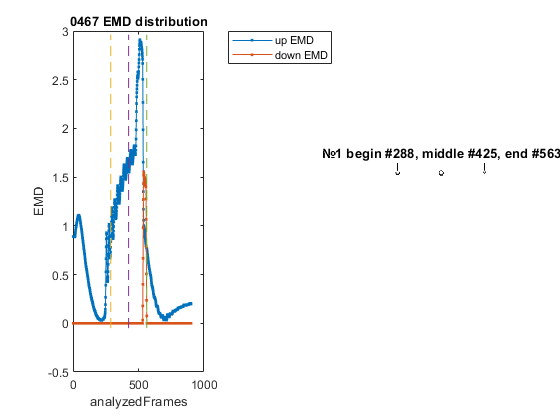

Figure & template were saved


Last row:


Saved row:


    {[467]}    {'288-563'}



33) ANALYZING: 0468_photron_avi.avi


Count of detected crops: 1


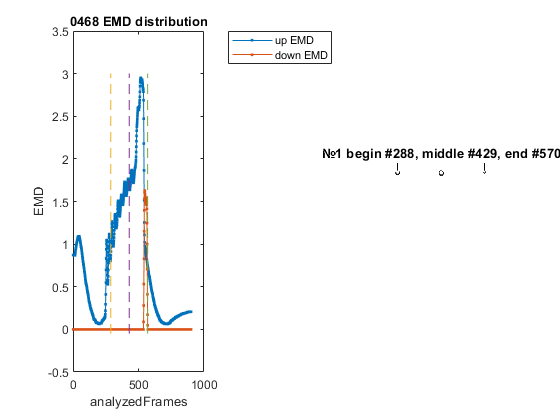

Figure & template were saved


Last row:


Saved row:


    {[468]}    {'288-570'}



34) ANALYZING: 0469_photron_avi.avi


Count of detected crops: 1


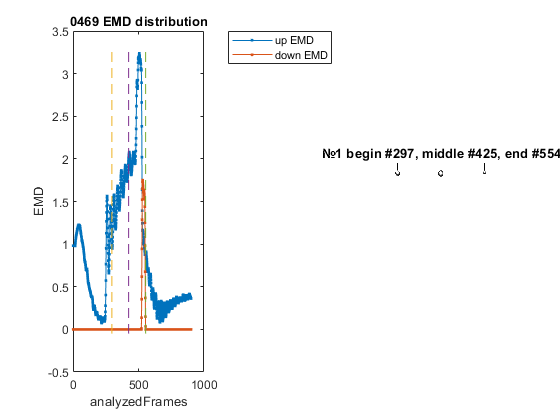

Figure & template were saved


Last row:


Saved row:


    {[469]}    {'297-554'}



35) ANALYZING: 0470_photron_avi.avi


Count of detected crops: 2


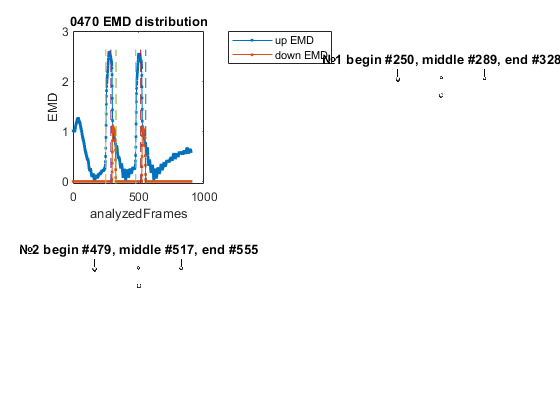

Figure & template were saved


Last row:


Saved row:


    {[470]}    {'250-328,479-555'}



36) ANALYZING: 0471_photron_avi.avi


Count of detected crops: 2


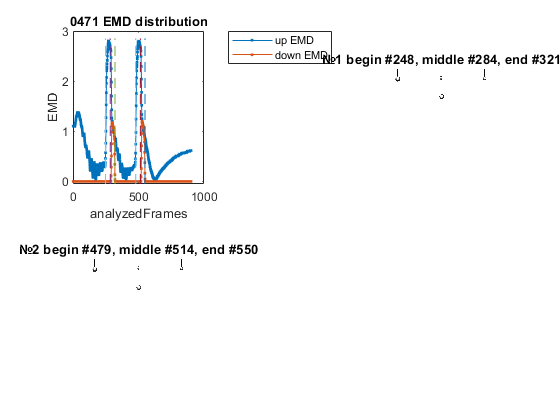

Figure & template were saved


Last row:


Saved row:


    {[471]}    {'248-321,479-550'}



37) ANALYZING: 0472_photron_avi.avi


Count of detected crops: 2


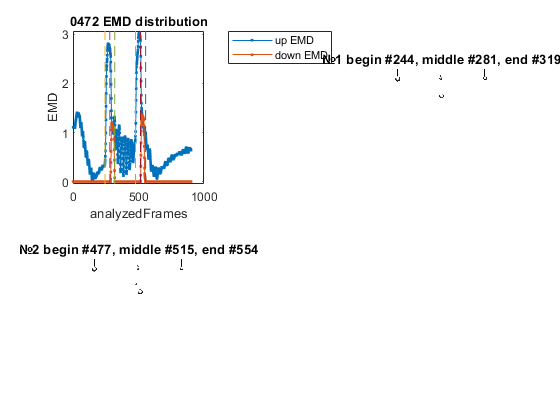

Figure & template were saved


Last row:


Saved row:


    {[472]}    {'244-319,477-554'}



38) ANALYZING: 0473_photron_avi.avi


Count of detected crops: 2


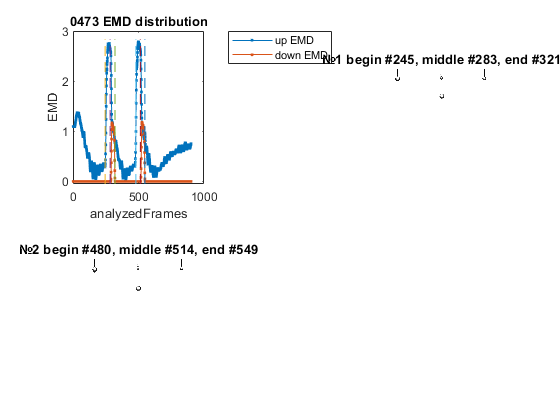

Figure & template were saved


Last row:


Saved row:


    {[473]}    {'245-321,480-549'}



39) ANALYZING: 0474_photron_avi.avi


Count of detected crops: 1


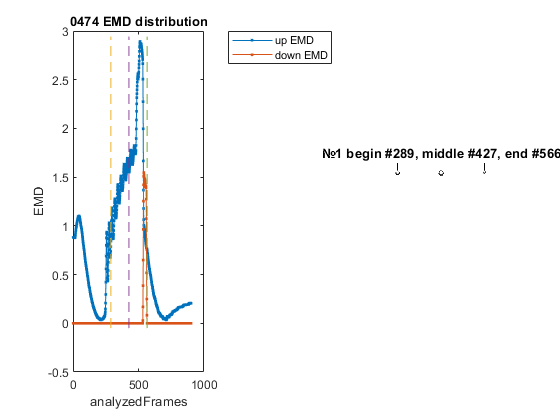

Figure & template were saved


Last row:


Saved row:


    {[474]}    {'289-566'}



40) ANALYZING: 0475_photron_avi.avi


Count of detected crops: 1


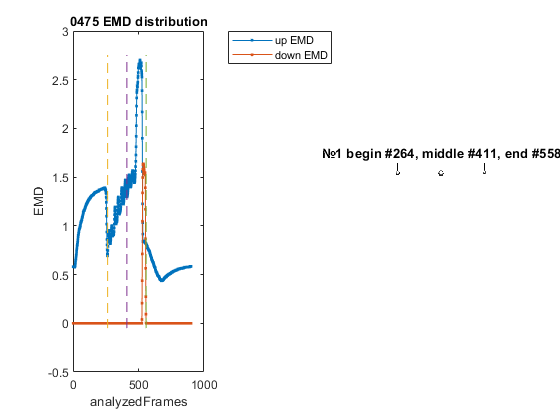

Figure & template were saved


Last row:


Saved row:


    {[475]}    {'264-558'}



41) ANALYZING: 0476_photron_avi.avi


Count of detected crops: 2


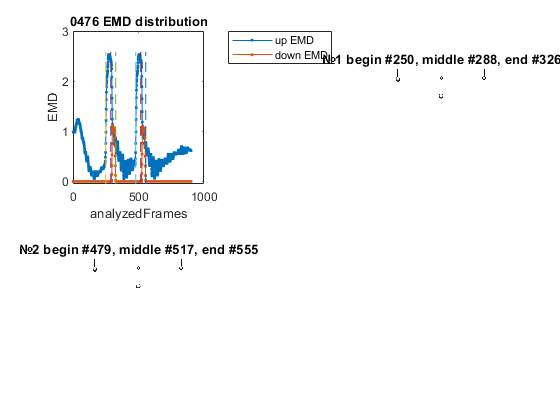

Figure & template were saved


Last row:


Saved row:


    {[476]}    {'250-326,479-555'}



42) ANALYZING: 0477_photron_avi.avi


Count of detected crops: 2


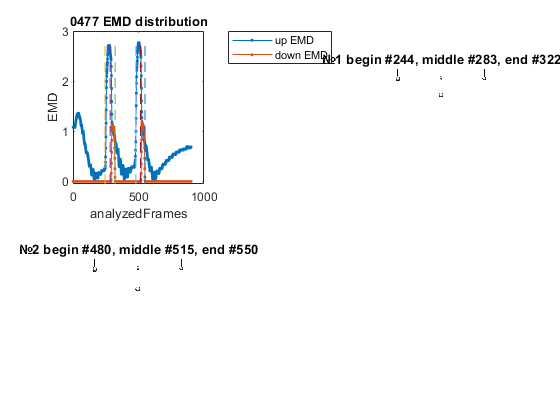

Figure & template were saved


Last row:


Saved row:


    {[477]}    {'244-322,480-550'}



43) ANALYZING: 0478_photron_avi.avi


Count of detected crops: 2


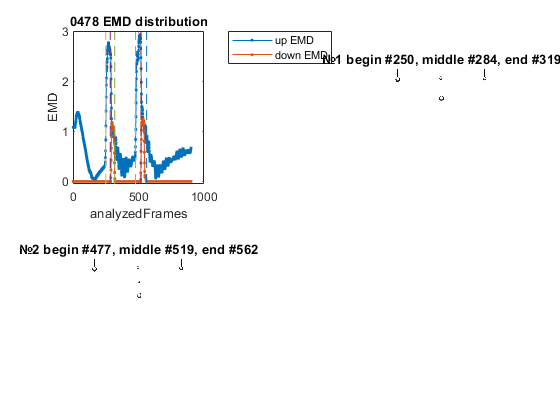

Figure & template were saved


Last row:


Saved row:


    {[478]}    {'250-319,477-562'}



44) ANALYZING: 0479_photron_avi.avi


Count of detected crops: 1


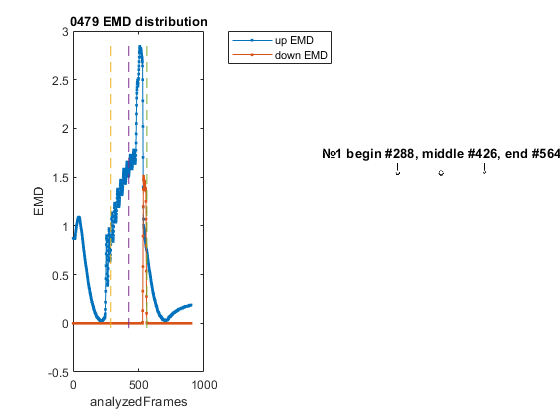

Figure & template were saved


Last row:


Saved row:


    {[479]}    {'288-564'}



45) ANALYZING: 0480_photron_avi.avi


Count of detected crops: 1


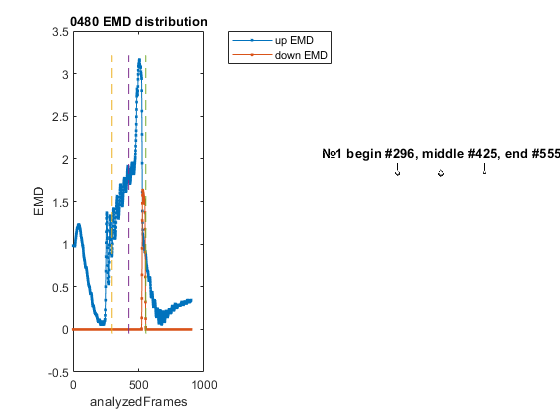

Figure & template were saved


Last row:


Saved row:


    {[480]}    {'296-555'}



46) ANALYZING: 0481_photron_avi.avi


Count of detected crops: 2


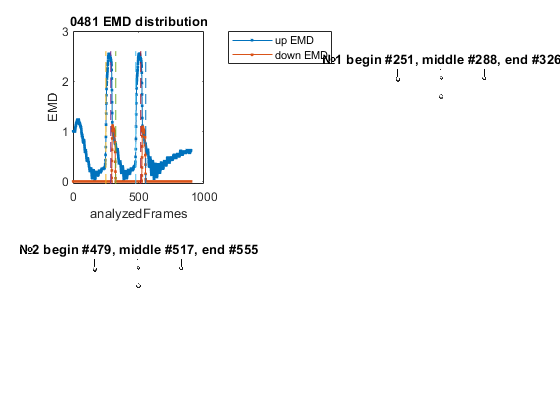

Figure & template were saved


Last row:


Saved row:


    {[481]}    {'251-326,479-555'}



47) ANALYZING: 0482_photron_avi.avi


Count of detected crops: 2


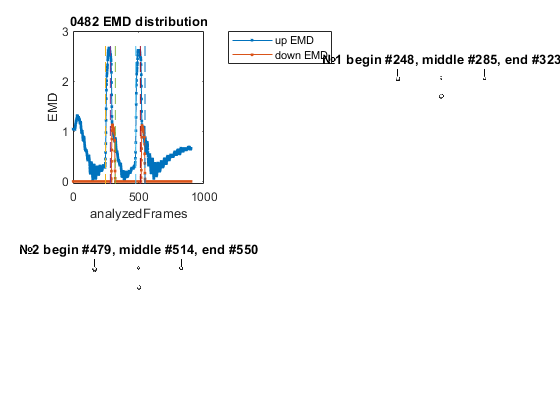

Figure & template were saved


Last row:


Saved row:


    {[482]}    {'248-323,479-550'}



48) ANALYZING: 0483_photron_avi.avi


Count of detected crops: 2


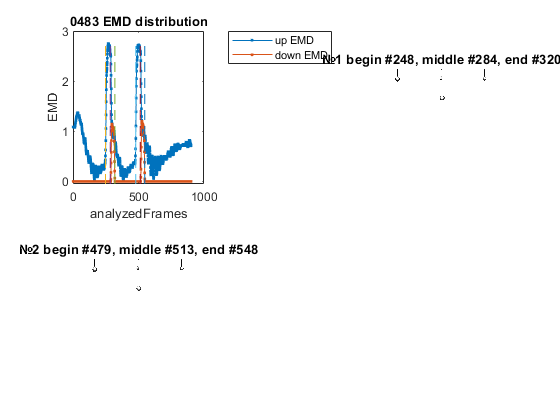

Figure & template were saved


Last row:


Saved row:


    {[483]}    {'248-320,479-548'}



49) ANALYZING: 0484_photron_avi.avi


Count of detected crops: 3


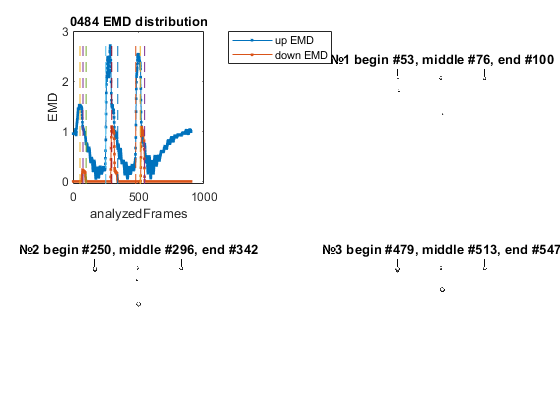

Figure & template were saved


Last row:


Saved row:


    {[484]}    {'53-100,250-342,479-547'}



50) ANALYZING: 0485_photron_avi.avi


Count of detected crops: 1


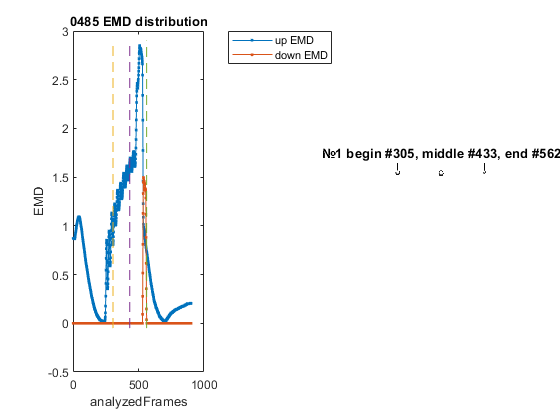

Figure & template were saved


Last row:


Saved row:


    {[485]}    {'305-562'}




 

%ANALYZE VIDEOS
for cellNum = loadRange(1):loadRange(2) %!!!! parfor cellNum = loadRange(1):loadRange(2)
    currentVideoName = allVideoNames{cellNum};
    if ~isempty(find(contains(analyzeCell, currentVideoName), 1))
        disp(strcat(string(cellNum),") ANALYZING: ", currentVideoName));
     
        obj = allObj{cellNum};
        video = allVideos{cellNum};
        frameRange = [1 allObj{cellNum}.NumFrames];
        
        % current test number
        text = split(currentVideoName,'_');
        testNum = uint16(str2double(text(1)));
    
        % ANALYZE!
        [selectedFrames, analyzedFrames, EMD,...
    templateImg] = cropVideoEMD(obj, video, frameRange, threshold,...
    upScaleKoef, downScaleKoef, frameLimit, smoothSpan, polyOrder,...
    baseFrameSide, maxEMDQuantileValue, maxSecDifQuantileValue,...
    UpDownKoef, quantileThreshold);

        % DISPLAY EMD-Values and images
        figure;
        dispFrames(selectedFrames, analyzedFrames, EMD, video, ...
            testNum);
        % SAVE EMD-Values and images as fig.
        figPath = strcat(croppingFolderPath, '\',sprintf('%04u',testNum), ...
            "_EMD",".fig");
        savefig(figPath);
        %close(gcf);
        templPath = strcat(croppingFolderPath, '\',sprintf('%04u',testNum),...
        "_template",".jpg");
        imwrite(templateImg,templPath)
        disp("Figure & template were saved");
        
        % SAVING CROP-RANGE
        
        % Create ranges of crop in string format
        cropRanges = cropRanges2str(selectedFrames);
        
        % READ TABLE
        T = readtable(dataPath);
        
        % delete previos ranges
        toDelete = T.test == testNum;
        lastrow = T(toDelete,:);
        T(toDelete,:) = [];
        % add new value
        savedRow = {testNum,cropRanges};
        T = [T;savedRow];
        
        % WRITE TABLE
        writetable(T,dataPath);
        disp('Last row:');
        disp(lastrow);
        disp('Saved row:');
        disp(savedRow);
    end
end